clear all;
clc;

Ref:[一阶倒立摆的PID控制和LQR控制 - 知乎 (zhihu.com)](https://zhuanlan.zhihu.com/p/54071212?s_r=0)

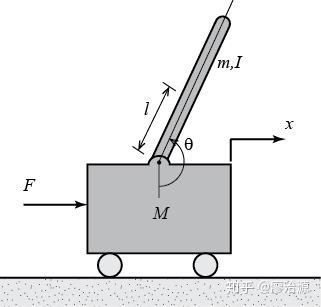

$M$-小车质量 $m$-摆质量 $l$-摆的重心到关节的距离 $I$-摆的转动惯量 $b$-阻尼系数 $F$-作用在小车上的力 $x$-小车位置 $\theta$-摆的角度

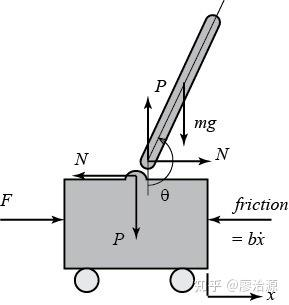

一顿操作得到摆的角度的传递函数:

Ppend(s)=\frac{Φ(s)}{U(s)}=\frac{mls}{qs^3+b(I+ml^2)s^2−(M+m)mgls−bmgl}

小车位置的传递函数:

Pcart(s)=\frac{X(s)}{U(s)}=\frac{(I+ml^2)s^2−mgl}{qs^4+b(I+ml^2)s^3−(M+m)mgls^2−bmgls}

其中 q 为:q=(M+m)(I+ml^2)−(ml)^2

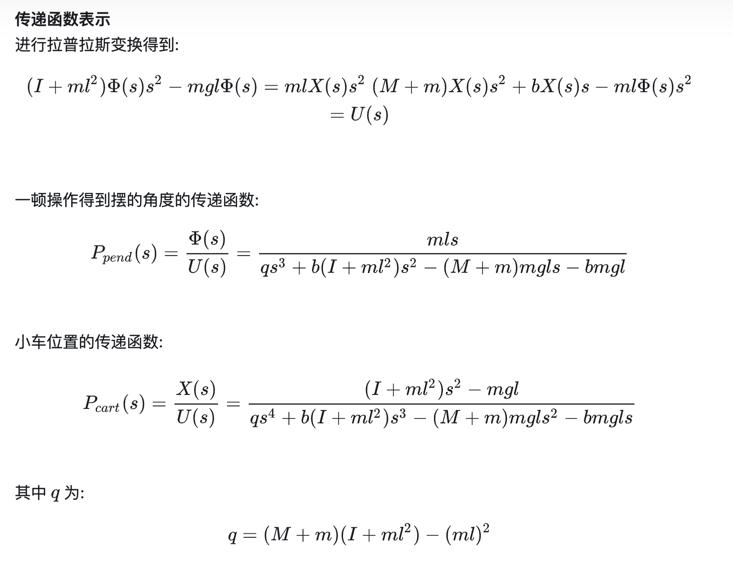

mCart=0.5;
mPend=0.2;
b=0.1;
I=0.018;
g=9.8;
L=0.3

L =    0.300000000000000



q=(mCart+mPend)*(I+mPend*L^2)-(mPend*L)^2;
s=tf('s');
P_cart = (((I+mPend*L^2)/q)*s^2 - (mPend*g*L/q))/(s^4 + (b*(I + mPend*L^2))*s^3/q - ((mCart + mPend)*mPend*g*L)*s^2/q - b*mPend*g*L*s/q);
P_pend = (mPend*L*s/q)/(s^3 + (b*(I + mPend*L^2))*s^2/q - ((mCart + mPend)*mPend*g*L)*s/q - b*mPend*g*L/q);
sys_tf = [P_cart ; P_pend]

sys_tf =
 
  从输入到输出...
                       1.68e-05 s^2 - 0.0002743
   1:  ---------------------------------------------------------
       1.008e-05 s^4 + 1.68e-06 s^3 - 0.000192 s^2 - 2.743e-05 s
 
                            2.799e-05 s
   2:  -----------------------------------------------------
       1.008e-05 s^3 + 1.68e-06 s^2 - 0.000192 s - 2.743e-05
 
连续时间传递函数。
模型属性


inputs = {'u'};
outputs = {'x'; 'phi'};
set(sys_tf,'InputName',inputs);
set(sys_tf,'OutputName',outputs);

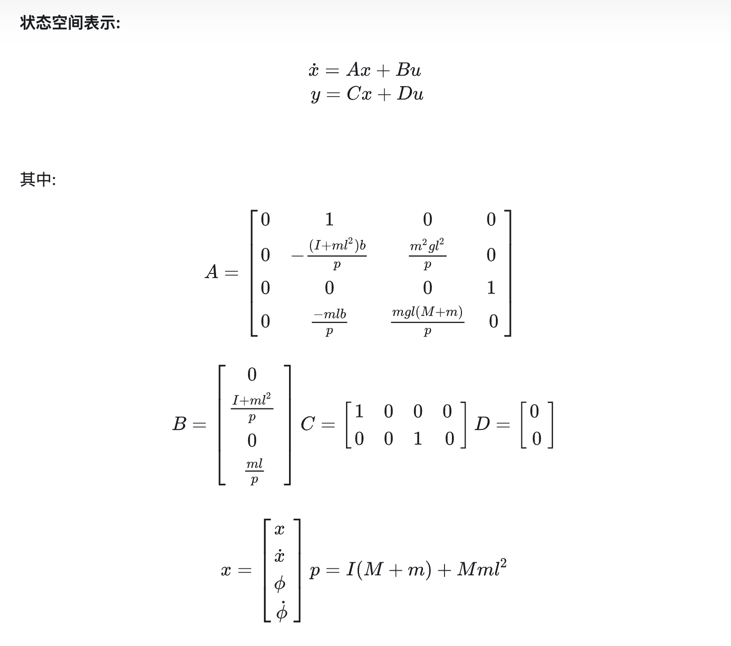


p = I*(mCart+mPend)+mCart*mPend*L^2;
 A = [0      1              0           0;
      0 -(I+mPend*L^2)*b/p  (mPend^2*g*L^2)/p   0;
      0      0              0           1;
      0 -(mPend*L*b)/p       mPend*g*L*(mCart+mPend)/p  0];
 B = [     0;
      (I+mPend*L^2)/p;
           0;
         mPend*L/p];
 C = [1 0 0 0;
      0 0 1 0];
 D = [0;
      0];
 states = {'x' 'x_dot' 'phi' 'phi_dot'};
 inputs = {'u'}; outputs = {'x'; 'phi'};
 sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

pole(sys_tf)

ans =                    0
   4.353755620948711
  -4.377590662547943
  -0.142831625067434
   4.353755620948711
  -4.377590662547943
  -0.142831625067434


pole(sys_ss)

ans =                    0
  -4.377590662547947
  -0.142831625067434
   4.353755620948714
